load ToxicoQAQCdataset.mat 
ind = rankfeatures(toxY,toxgrp,'Criterion','ttest','NumberOfIndices',100);
z = toxY(ind,:);
p = double(strcmp('ToxDef',toxgrp));
l = [p p-1];
[z,l] = toxic_dataset;

l =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


whos z l

  Name        Size            Bytes  Class     Attributes

  l           2x62              992  double              
  z         100x62            49600  double              



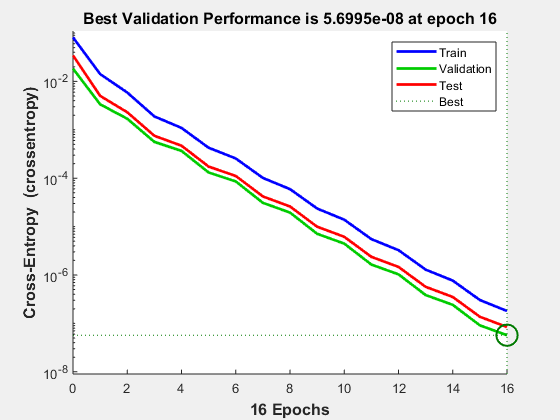

setdemorandstream(672587951)
net = patternnet(5);
view(net)
[net,tr] = train(net,z,l);
plotperform(tr)

testX = z(:,tr.testInd);
testT = l(:,tr.testInd);

testY = net(testX);
testClasses = testY > 0.5

testClasses = 2×9 logical array
   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0


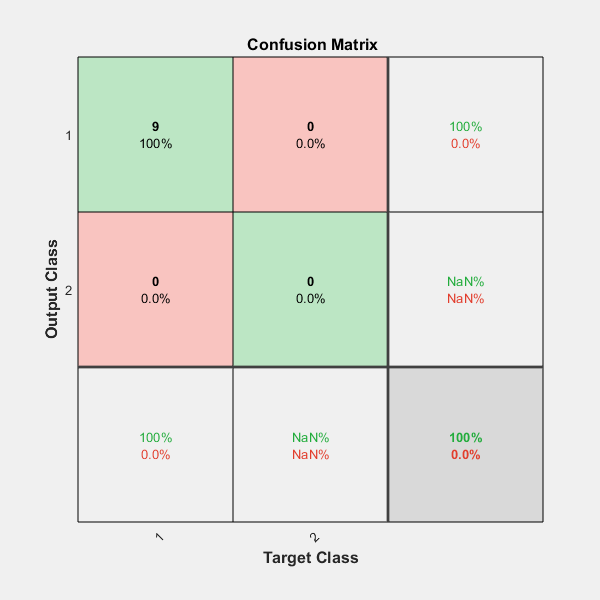

plotconfusion(testT,testY)

[c,cm] = confusion(testT,testY);

fprintf('Percentage Correct Classification   : %f%%\n', 100*(1-c));

Percentage Correct Classification   : 33.333333%


fprintf('Percentage Incorrect Classification : %f%%\n', 100*c);

Percentage Incorrect Classification : 66.666667%


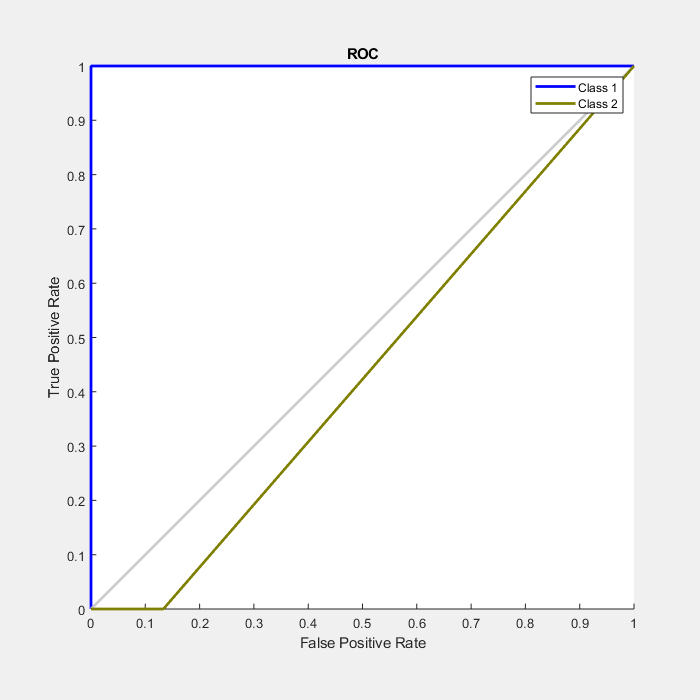

plotroc(testT,testY)